# Notes regarding lab format

Name : Apoorva Udayakumar

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder, any output images you might have saved and this livescript file (with the required images plotted).

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('/Users/apoorva/Documents/ImageAnalysisProject_Apoorva_Udayakumar/functions');
addpath('/Users/apoorva/Documents/ImageAnalysisProject_Apoorva_Udayakumar/data');


## Generative Neural Networks

We are using the MNIST dataset for to implement the VAE to generate digits between 0-9.

Load the MINST dataset by reading the files. 

trainingImages = 'train-images.idx3-ubyte';
testingImages = 't10k-images.idx3-ubyte';
testLabels = 't10k-labels.idx1-ubyte';
trainLabels = 'train-labels.idx1-ubyte';

train_images = processImagesMNIST(trainingImages);


Read MNIST image data...
Number of images in the dataset:  60000 ...


train_labels = processLabelsMNIST(trainLabels);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


test_images = processImagesMNIST(testingImages);


Read MNIST image data...
Number of images in the dataset:  10000 ...


test_labels = processLabelsMNIST(testLabels);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


 Encoder and Decoder Network:

latentspace_Dimension = 2;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

## Base Model:

number_of_Epochs = 20;
batchSize = 512;
learningrate = 1e-3;
momentum =[];
[encoderNet_trained,decoderNet_trained]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 27.7183. Time taken for epoch = 49.1065s
Epoch : 2 Test ELBO loss = 26.3441. Time taken for epoch = 45.4448s
Epoch : 3 Test ELBO loss = 25.7507. Time taken for epoch = 43.3942s
Epoch : 4 Test ELBO loss = 25.2958. Time taken for epoch = 42.8145s
Epoch : 5 Test ELBO loss = 25.0271. Time taken for epoch = 44.6145s
Epoch : 6 Test ELBO loss = 24.3444. Time taken for epoch = 43.72s
Epoch : 7 Test ELBO loss = 23.9701. Time taken for epoch = 42.3779s
Epoch : 8 Test ELBO loss = 23.6436. Time taken for epoch = 42.1262s
Epoch : 9 Test ELBO loss = 23.4878. Time taken for epoch = 43.9426s
Epoch : 10 Test ELBO loss = 23.3308. Time taken for epoch = 42.1613s
Epoch : 11 Test ELBO loss = 23.1072. Time taken for epoch = 41.7332s
Epoch : 12 Test ELBO loss = 22.9604. Time taken for epoch = 40.8999s
Epoch : 13 Test ELBO loss = 22.8898. Time taken for epoch = 40.9346s
Epoch : 14 Test ELBO loss = 22.7009. Time taken for epoch = 40.914s
Epoch : 15 Test ELBO loss = 22.6557. Time take

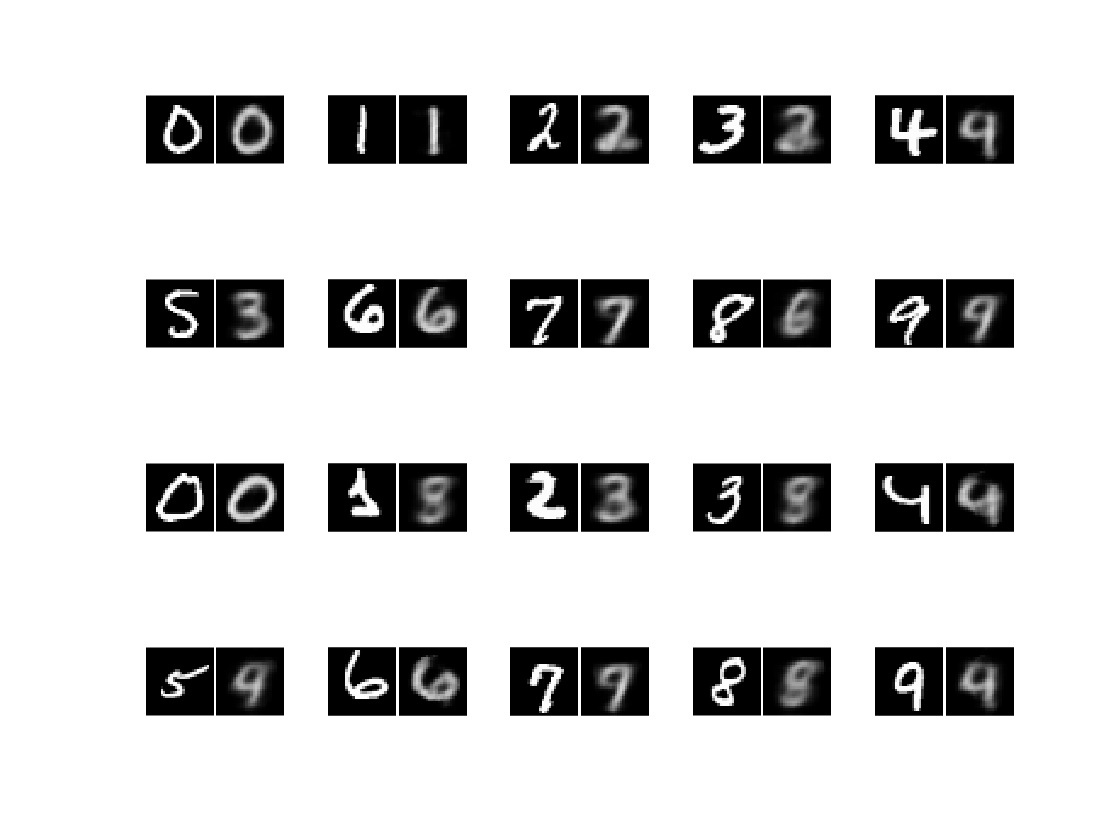

visualizeReconstruction(test_images, test_labels, encoderNet_trained,decoderNet_trained);

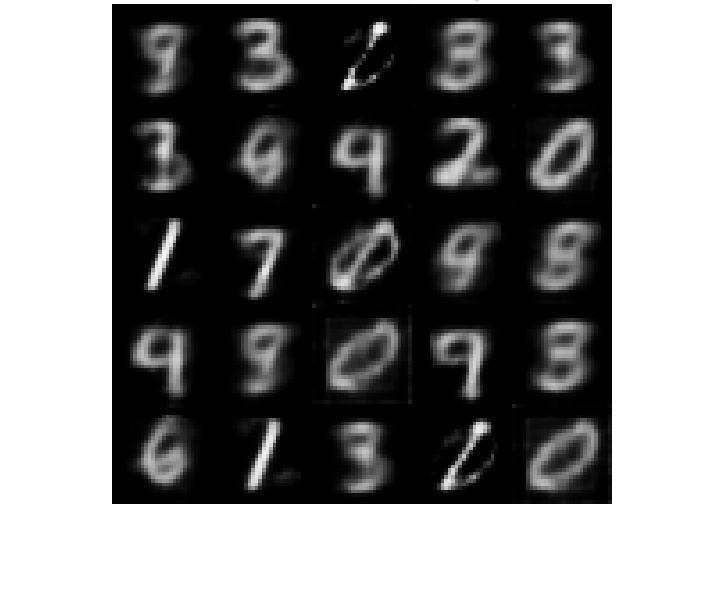

generate(decoderNet_trained, latentspace_Dimension)

**Latent  Space Representation:**

**Here I have used the z= latent space that is outputed from the encoder to represent the images compressed.**

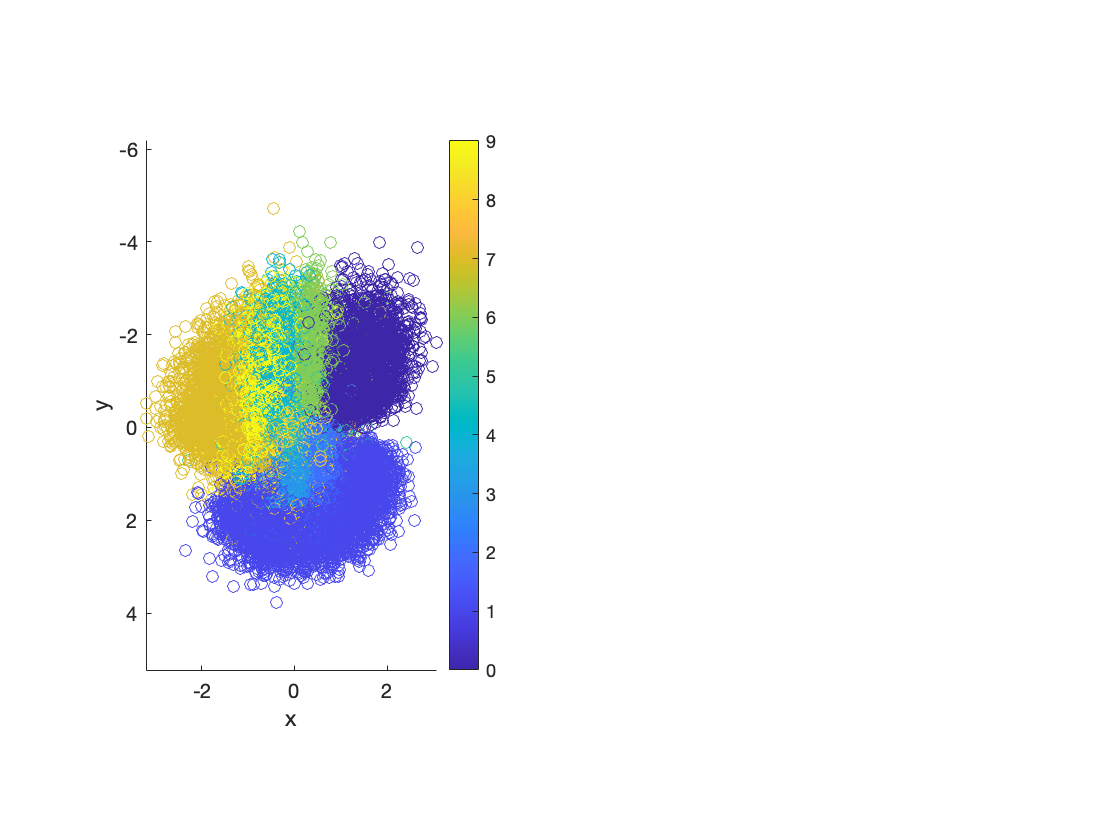

compressed = forward(encoderNet_trained,train_images);
d = size(compressed,1)/2;
zMean = compressed(1:d,:);
zLogvar = compressed(1+d:end,:);

sz = size(zMean);
epsilon = randn(sz);
sigma = exp(.5 * zLogvar);
z = epsilon .* sigma + zMean;
zMean = stripdims(z)';
zMean = gather(extractdata(zMean));

[~,score] = pca(zMean);

c = parula(10);
f1 = figure;
figure(f1)
title("Latent space")

ah = subplot(1,2,1);
scatter(score(:,2),score(:,1),[],c(double(train_labels),:));
ah.YDir = 'reverse';
axis equal
xlabel("x")
ylabel("y")
cb = colorbar; cb.Ticks = 0:(1/9):1; cb.TickLabels = string(0:9);

**Generation of specific class digit :**

**Here by visualizing the latent space representation I have taken a point that represent that specific class and used to generate the class-specific image by giving the point (coordinates) to decoder network.**

**the below code where b(:,:,1) represent the y-coordinate and b(:,:,2) represent the x-coordinate. So, by visulaizing I have taken the point(2,1 ) to produce the digit 1.**

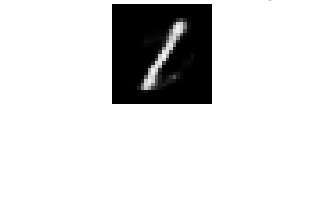

b (:,:,1)= 2;
b(:,:,2) = 1;
randomNoise = dlarray(b,'SSCB');
generatedImage = sigmoid(predict(decoderNet_trained, randomNoise));
generatedImage = extractdata(generatedImage);

f3 = figure;
figure(f3)
imshow(imtile(generatedImage, "ThumbnailSize", [100,100]))
title("Generated sample of digits")

drawnow

** by visulaizing I have taken the point(-2,-2) to produce the digit 9.**

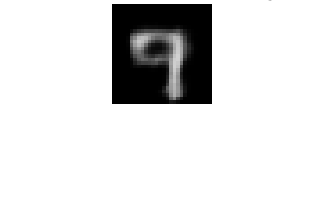


b (:,:,1)= -2;
b(:,:,2) = -2;
randomNoise = dlarray(b,'SSCB');
generatedImage = sigmoid(predict(decoderNet_trained, randomNoise));
generatedImage = extractdata(generatedImage);

f3 = figure;
figure(f3)
imshow(imtile(generatedImage, "ThumbnailSize", [100,100]))
title("Generated sample of digits")

drawnow

**by visulaizing I have taken the point(1,-1) to produce the digit 0.**

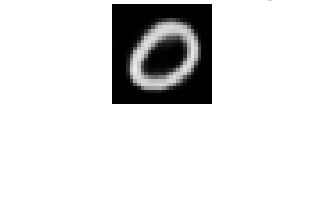


b (:,:,1)= 1;
b(:,:,2) = -1;
randomNoise = dlarray(b,'SSCB');
generatedImage = sigmoid(predict(decoderNet_trained, randomNoise));
generatedImage = extractdata(generatedImage);

f3 = figure;
figure(f3)
imshow(imtile(generatedImage, "ThumbnailSize", [100,100]))
title("Generated sample of digits")

drawnow

**Similarly for the other class digits we can specify the coordinate in the range by the latent space visualization.**

Test 1: Reduce the batch size by half from 512/2 = 256

latentspace_Dimension = 2;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 50;
batchSize = 256;
learningrate = 1e-3;
momentum =[];
[encoderNet_trained_test1,decoderNet_trained_test1]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 26.9469. Time taken for epoch = 45.5829s
Epoch : 2 Test ELBO loss = 25.8451. Time taken for epoch = 43.7208s
Epoch : 3 Test ELBO loss = 24.7944. Time taken for epoch = 42.4444s
Epoch : 4 Test ELBO loss = 24.0387. Time taken for epoch = 42.54s
Epoch : 5 Test ELBO loss = 23.6522. Time taken for epoch = 44.1709s
Epoch : 6 Test ELBO loss = 23.4752. Time taken for epoch = 43.7987s
Epoch : 7 Test ELBO loss = 23.2467. Time taken for epoch = 43.1858s
Epoch : 8 Test ELBO loss = 23.0717. Time taken for epoch = 43.9782s
Epoch : 9 Test ELBO loss = 22.959. Time taken for epoch = 42.8336s
Epoch : 10 Test ELBO loss = 22.8816. Time taken for epoch = 44.0906s
Epoch : 11 Test ELBO loss = 22.8145. Time taken for epoch = 42.8176s
Epoch : 12 Test ELBO loss = 22.7146. Time taken for epoch = 44.4039s
Epoch : 13 Test ELBO loss = 22.7208. Time taken for epoch = 43.2068s
Epoch : 14 Test ELBO loss = 22.5604. Time taken for epoch = 42.4503s
Epoch : 15 Test ELBO loss = 22.5703. Time take

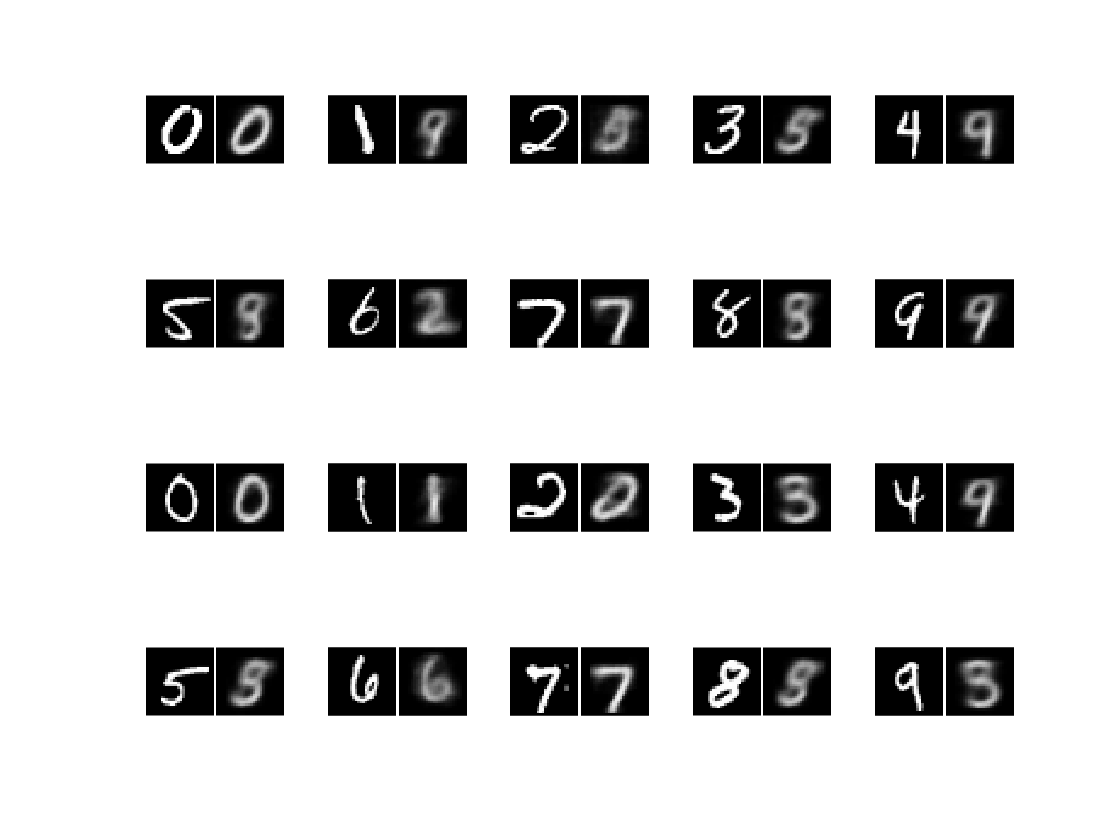


visualizeReconstruction(test_images, test_labels, encoderNet_trained_test1, decoderNet_trained_test1);

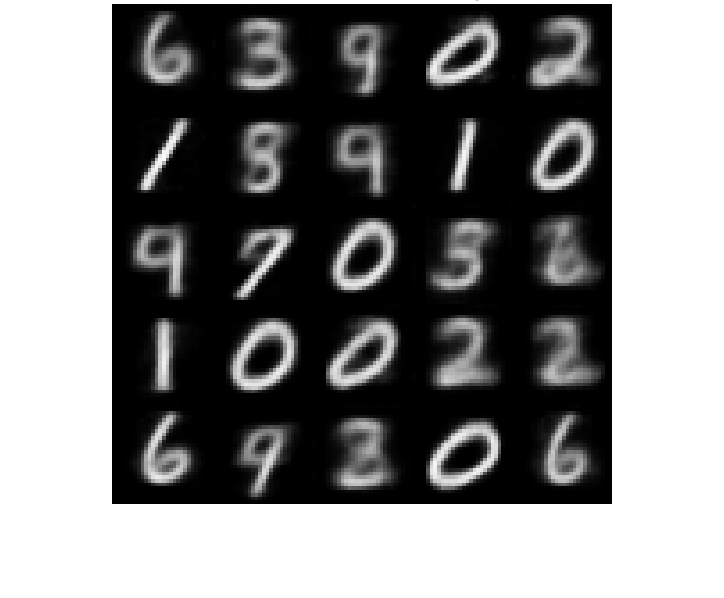

generate(decoderNet_trained_test1,latentspace_Dimension);

Test 2: Reduce the batch size by quater from 512/4 = 128

latentspace_Dimension = 2;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 50;
batchSize = 128;
learningrate = 1e-3;
momentum =[];
[encoderNet_trained_test2,decoderNet_trained_test2]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 25.8435. Time taken for epoch = 53.2732s
Epoch : 2 Test ELBO loss = 24.6807. Time taken for epoch = 52.9122s
Epoch : 3 Test ELBO loss = 24.034. Time taken for epoch = 57.2578s
Epoch : 4 Test ELBO loss = 23.8596. Time taken for epoch = 58.2553s
Epoch : 5 Test ELBO loss = 23.6785. Time taken for epoch = 50.9222s
Epoch : 6 Test ELBO loss = 23.3702. Time taken for epoch = 52.6405s
Epoch : 7 Test ELBO loss = 22.9987. Time taken for epoch = 53.5609s
Epoch : 8 Test ELBO loss = 22.8324. Time taken for epoch = 53.1263s
Epoch : 9 Test ELBO loss = 22.5593. Time taken for epoch = 53.12s
Epoch : 10 Test ELBO loss = 22.6365. Time taken for epoch = 53.9962s
Epoch : 11 Test ELBO loss = 22.3159. Time taken for epoch = 53.0928s
Epoch : 12 Test ELBO loss = 22.2447. Time taken for epoch = 51.6555s
Epoch : 13 Test ELBO loss = 22.0846. Time taken for epoch = 51.4066s
Epoch : 14 Test ELBO loss = 21.9785. Time taken for epoch = 51.7127s
Epoch : 15 Test ELBO loss = 21.8937. Time take

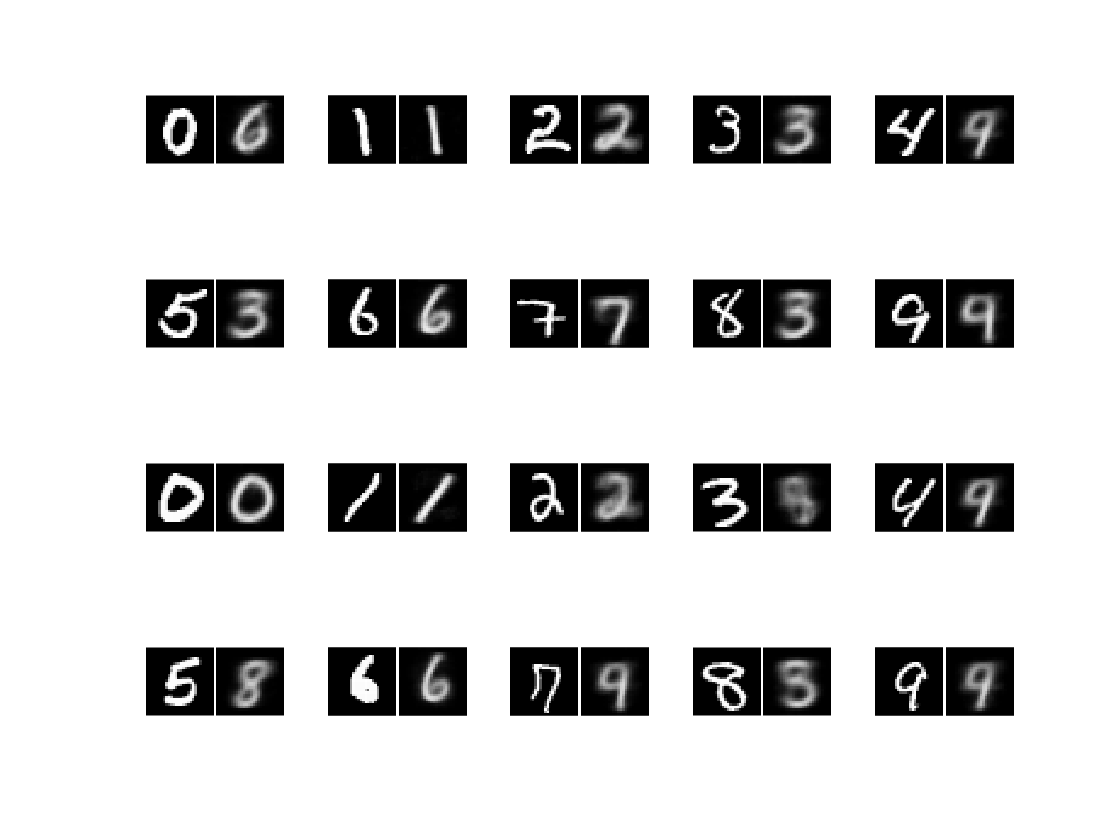

visualizeReconstruction(test_images, test_labels, encoderNet_trained_test2, decoderNet_trained_test2);

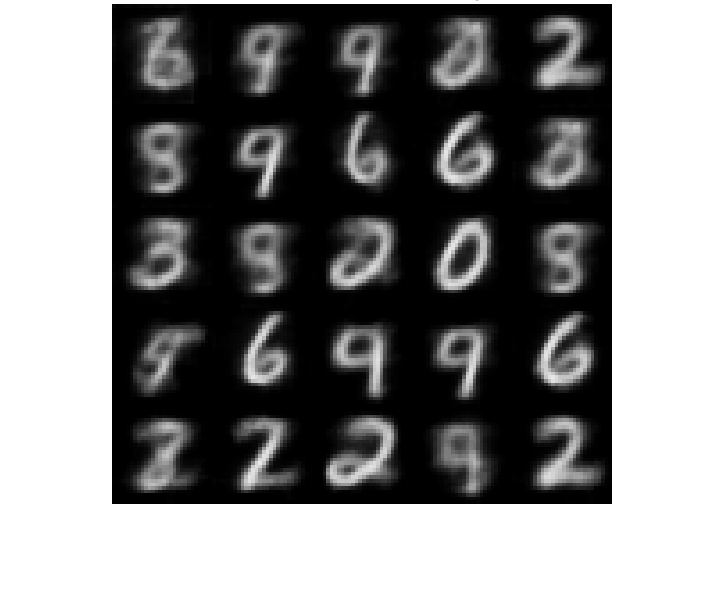

generate(decoderNet_trained_test2, latentspace_Dimension);

Test3: Reduce the Epoch to 30.

latentspace_Dimension = 2;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 30;
batchSize = 512;
learningrate = 1e-3;
momentum =[];
[encoderNet_trained_test3,decoderNet_trained_test3]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 28.3886. Time taken for epoch = 41.1299s
Epoch : 2 Test ELBO loss = 26.5763. Time taken for epoch = 39.4031s
Epoch : 3 Test ELBO loss = 25.843. Time taken for epoch = 39.365s
Epoch : 4 Test ELBO loss = 24.916. Time taken for epoch = 40.3692s
Epoch : 5 Test ELBO loss = 24.4392. Time taken for epoch = 38.7193s
Epoch : 6 Test ELBO loss = 24.0867. Time taken for epoch = 38.4915s
Epoch : 7 Test ELBO loss = 23.8517. Time taken for epoch = 38.4025s
Epoch : 8 Test ELBO loss = 23.6045. Time taken for epoch = 38.4453s
Epoch : 9 Test ELBO loss = 23.4618. Time taken for epoch = 38.5194s
Epoch : 10 Test ELBO loss = 23.3122. Time taken for epoch = 38.237s
Epoch : 11 Test ELBO loss = 23.1293. Time taken for epoch = 38.5911s
Epoch : 12 Test ELBO loss = 22.9915. Time taken for epoch = 38.7403s
Epoch : 13 Test ELBO loss = 22.903. Time taken for epoch = 39.0713s
Epoch : 14 Test ELBO loss = 22.7802. Time taken for epoch = 38.7277s
Epoch : 15 Test ELBO loss = 22.6796. Time taken 

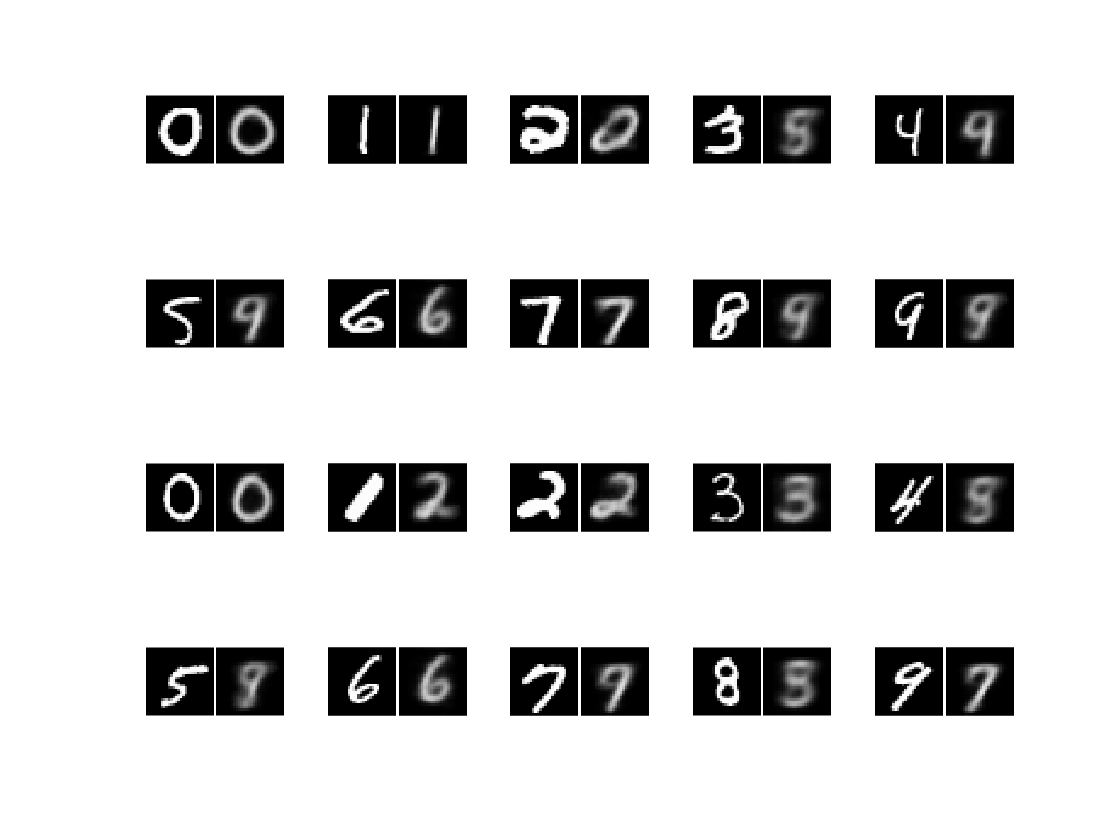

visualizeReconstruction(test_images, test_labels, encoderNet_trained_test3,decoderNet_trained_test3);

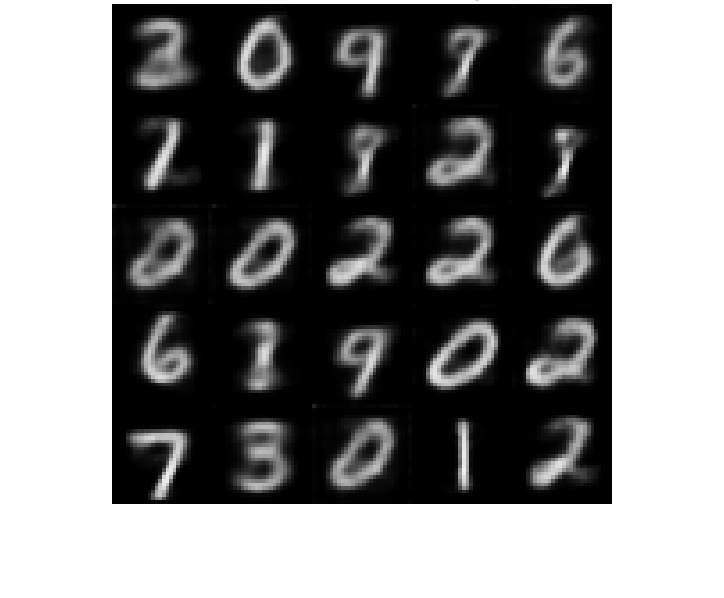

generate(decoderNet_trained_test3, latentspace_Dimension);

Test4:Decrease the learning rate 

image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 50;
batchSize = 512;
learningrate = 1e-5;
momentum = [];
[encoderNet_trained_test4,decoderNet_trained_test4]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 90.2612. Time taken for epoch = 40.7348s
Epoch : 2 Test ELBO loss = 89.268. Time taken for epoch = 38.9143s
Epoch : 3 Test ELBO loss = 87.3501. Time taken for epoch = 39.9415s
Epoch : 4 Test ELBO loss = 83.2678. Time taken for epoch = 39.0345s
Epoch : 5 Test ELBO loss = 75.5918. Time taken for epoch = 39.0571s
Epoch : 6 Test ELBO loss = 66.3337. Time taken for epoch = 39.3204s
Epoch : 7 Test ELBO loss = 58.6727. Time taken for epoch = 40.4412s
Epoch : 8 Test ELBO loss = 53.0271. Time taken for epoch = 40.5789s
Epoch : 9 Test ELBO loss = 48.62. Time taken for epoch = 40.2095s
Epoch : 10 Test ELBO loss = 45.008. Time taken for epoch = 39.1404s
Epoch : 11 Test ELBO loss = 42.1734. Time taken for epoch = 39.5709s
Epoch : 12 Test ELBO loss = 40.2262. Time taken for epoch = 38.4811s
Epoch : 13 Test ELBO loss = 38.6697. Time taken for epoch = 38.3807s
Epoch : 14 Test ELBO loss = 37.5121. Time taken for epoch = 38.4012s
Epoch : 15 Test ELBO loss = 36.5158. Time taken

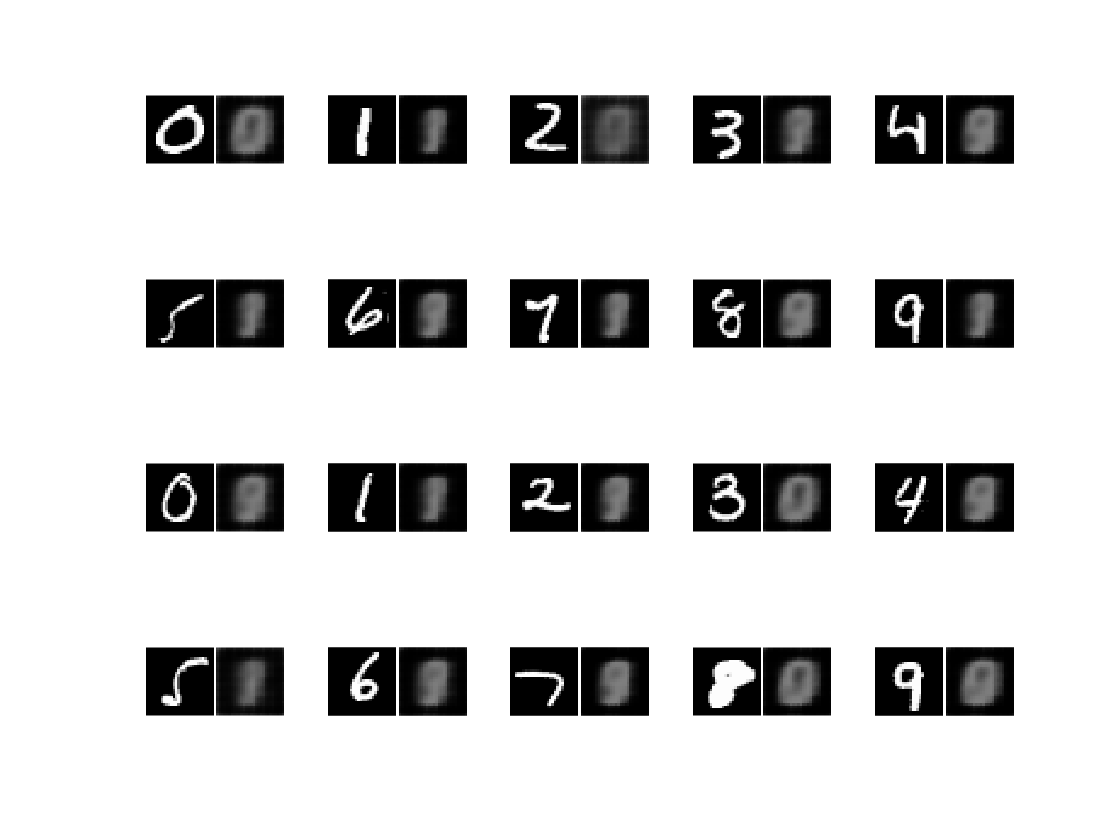

visualizeReconstruction(test_images, test_labels, encoderNet_trained_test4,decoderNet_trained_test4);

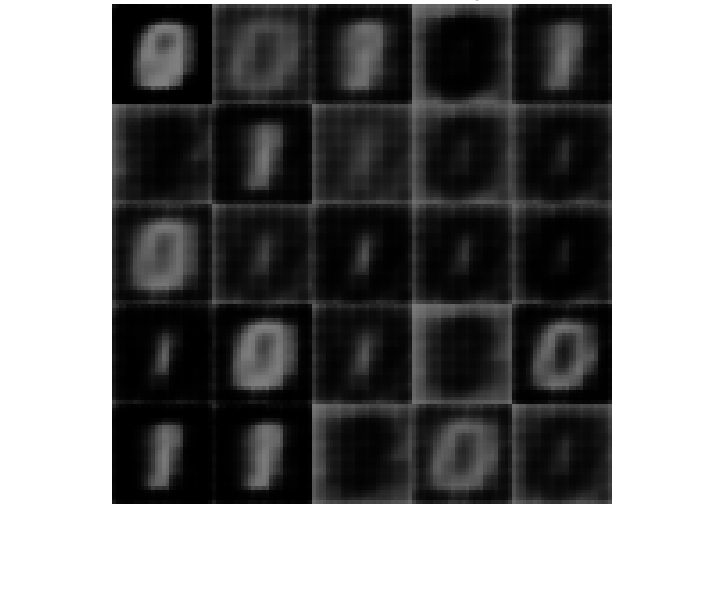

generate(decoderNet_trained_test4, latentspace_Dimension);

Test5 : Using sgdm optimizer by replacing adam

latentspace_Dimension = 2;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 50;
batchSize = 512;
learningrate = 1e-3;
momentum =[];
[encoderNet_trained_test5,decoderNet_trained_test5]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'sgdm');

Epoch : 1 Test ELBO loss = 37.1395. Time taken for epoch = 43.589s
Epoch : 2 Test ELBO loss = 36.8718. Time taken for epoch = 38.1097s
Epoch : 3 Test ELBO loss = 36.539. Time taken for epoch = 37.9685s
Epoch : 4 Test ELBO loss = 36.1275. Time taken for epoch = 37.9747s
Epoch : 5 Test ELBO loss = 36.2652. Time taken for epoch = 38.0761s
Epoch : 6 Test ELBO loss = 29.3331. Time taken for epoch = 37.9579s
Epoch : 7 Test ELBO loss = 27.3584. Time taken for epoch = 38.2593s
Epoch : 8 Test ELBO loss = 26.3071. Time taken for epoch = 38.4786s
Epoch : 9 Test ELBO loss = 25.7202. Time taken for epoch = 40.3789s
Epoch : 10 Test ELBO loss = 25.589. Time taken for epoch = 40.4457s
Epoch : 11 Test ELBO loss = 25.54. Time taken for epoch = 40.1213s
Epoch : 12 Test ELBO loss = 25.6639. Time taken for epoch = 40.0456s
Epoch : 13 Test ELBO loss = 25.485. Time taken for epoch = 40.1094s
Epoch : 14 Test ELBO loss = 25.2831. Time taken for epoch = 40.1471s
Epoch : 15 Test ELBO loss = 25.4314. Time taken f

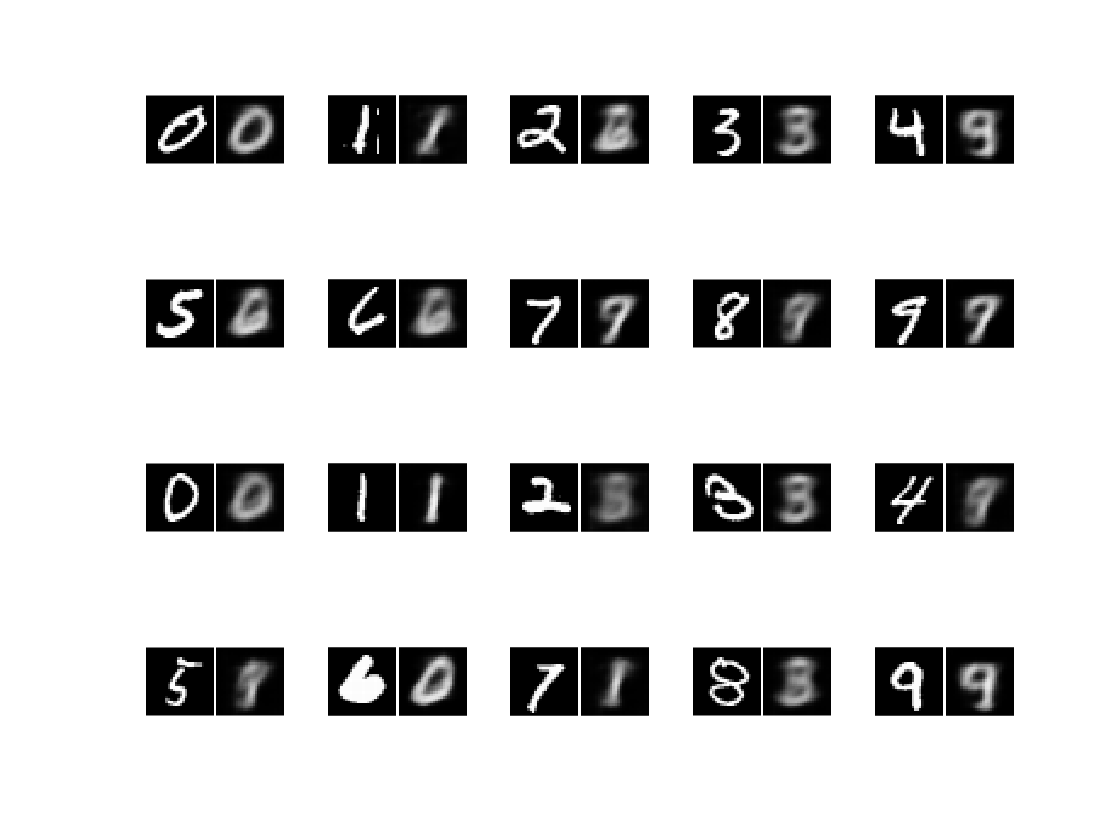

visualizeReconstruction(test_images, test_labels, encoderNet_trained_test5,decoderNet_trained_test5);

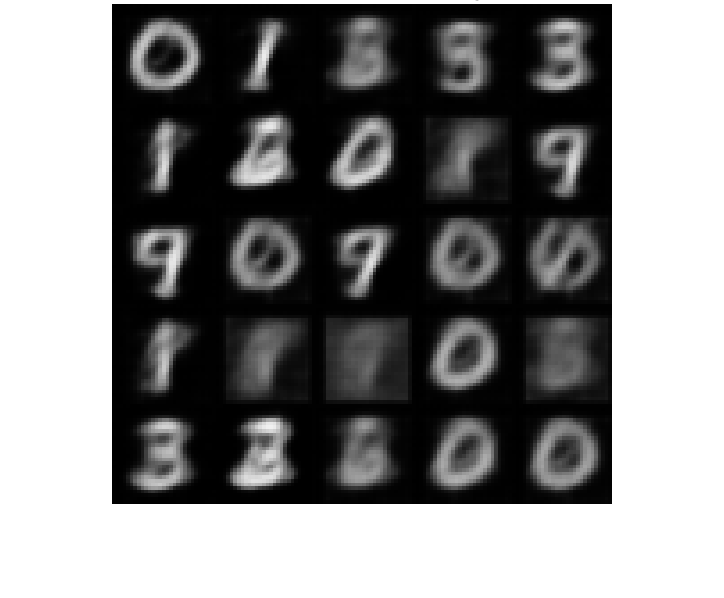

generate(decoderNet_trained_test5, latentspace_Dimension);

Test6: Change the filter size


latentspace_Dimension = 2;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(7, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(7, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(9, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(7, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(7, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 50;
batchSize = 512;
learningrate = 1e-3;
momentum =[];
[encoderNet_trained_test6,decoderNet_trained_test6]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 44.6717. Time taken for epoch = 93.7138s
Epoch : 2 Test ELBO loss = 44.6717. Time taken for epoch = 92.3508s
Epoch : 3 Test ELBO loss = 44.6716. Time taken for epoch = 92.0768s
Epoch : 4 Test ELBO loss = 44.6716. Time taken for epoch = 91.083s
Epoch : 5 Test ELBO loss = 44.6716. Time taken for epoch = 90.7965s
Epoch : 6 Test ELBO loss = 44.6716. Time taken for epoch = 88.5715s
Epoch : 7 Test ELBO loss = 44.6716. Time taken for epoch = 89.1739s
Epoch : 8 Test ELBO loss = 44.6716. Time taken for epoch = 88.3533s
Epoch : 9 Test ELBO loss = 44.6716. Time taken for epoch = 89.3233s
Epoch : 10 Test ELBO loss = 44.6716. Time taken for epoch = 89.3763s
Epoch : 11 Test ELBO loss = 44.6716. Time taken for epoch = 89.5745s
Epoch : 12 Test ELBO loss = 44.6716. Time taken for epoch = 90.448s
Epoch : 13 Test ELBO loss = 44.6716. Time taken for epoch = 91.0138s
Epoch : 14 Test ELBO loss = 44.6716. Time taken for epoch = 91.8373s
Epoch : 15 Test ELBO loss = 44.6716. Time tak

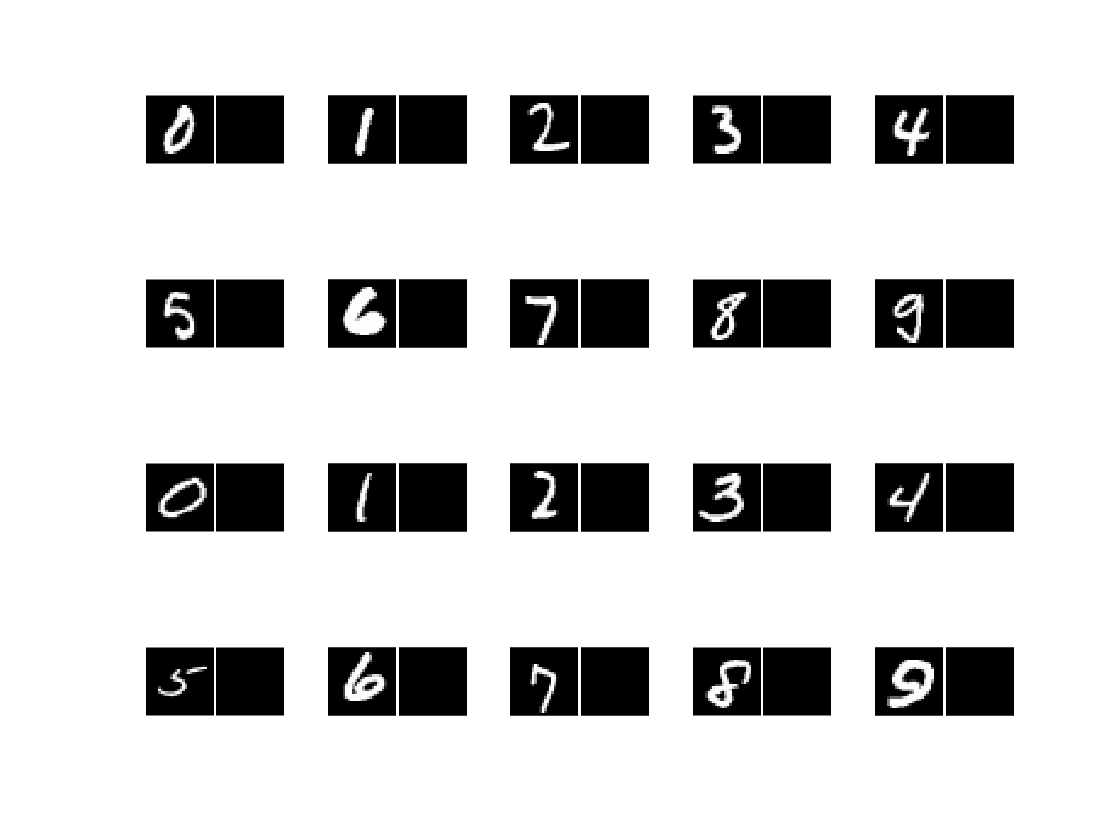

visualizeReconstruction(test_images, test_labels, encoderNet_trained_test6,decoderNet_trained_test6);

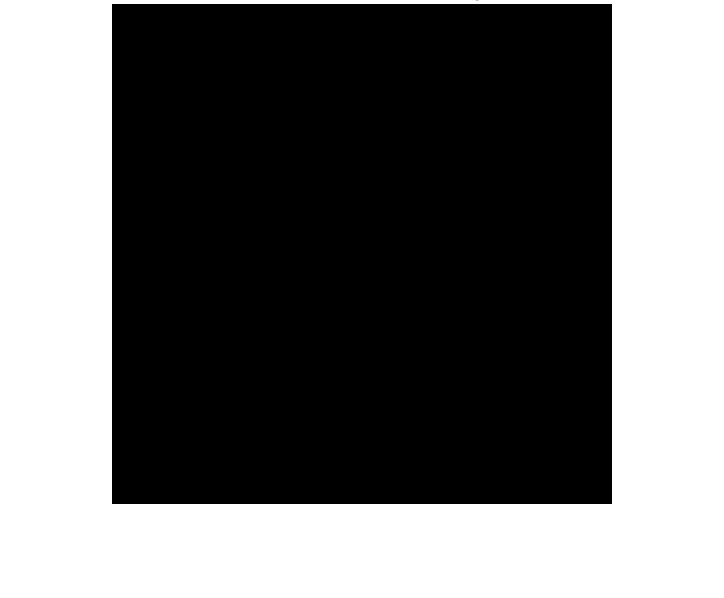

generate(decoderNet_trained_test6, latentspace_Dimension);

Test7 :Add new layer to the network

latentspace_Dimension = 2;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 50;
batchSize = 512;
learningrate = 1e-3;
momentum =[];
[encoderNet_trained_test7,decoderNet_trained_test7]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 28.3617. Time taken for epoch = 45.169s
Epoch : 2 Test ELBO loss = 27.3406. Time taken for epoch = 41.0815s
Epoch : 3 Test ELBO loss = 26.7528. Time taken for epoch = 42.0021s
Epoch : 4 Test ELBO loss = 25.6896. Time taken for epoch = 42.4482s
Epoch : 5 Test ELBO loss = 24.4002. Time taken for epoch = 41.0512s
Epoch : 6 Test ELBO loss = 23.8358. Time taken for epoch = 41.2768s
Epoch : 7 Test ELBO loss = 23.4958. Time taken for epoch = 41.2002s
Epoch : 8 Test ELBO loss = 23.2044. Time taken for epoch = 41.4201s
Epoch : 9 Test ELBO loss = 22.8807. Time taken for epoch = 41.2002s
Epoch : 10 Test ELBO loss = 22.6301. Time taken for epoch = 41.5459s
Epoch : 11 Test ELBO loss = 22.4882. Time taken for epoch = 42.3201s
Epoch : 12 Test ELBO loss = 22.377. Time taken for epoch = 41.131s
Epoch : 13 Test ELBO loss = 22.2307. Time taken for epoch = 41.9492s
Epoch : 14 Test ELBO loss = 22.2177. Time taken for epoch = 40.5569s
Epoch : 15 Test ELBO loss = 22. Time taken for

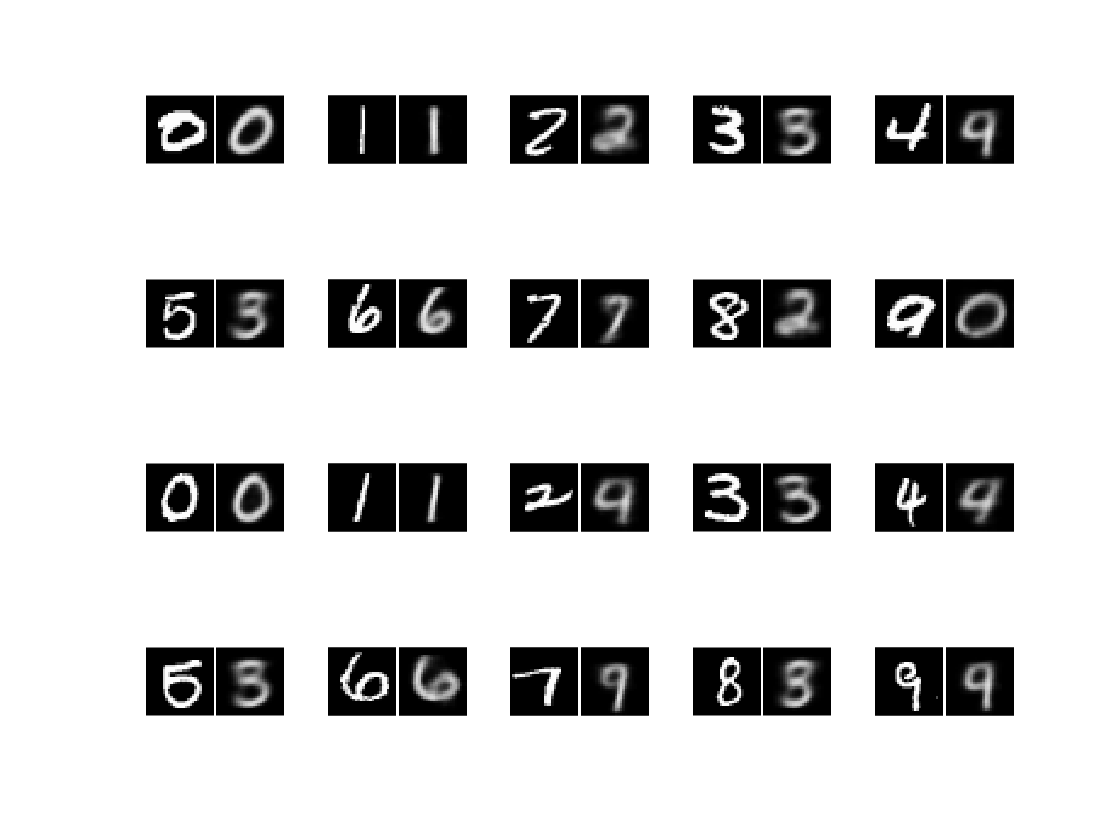

visualizeReconstruction(test_images, test_labels, encoderNet_trained_test7,decoderNet_trained_test7);

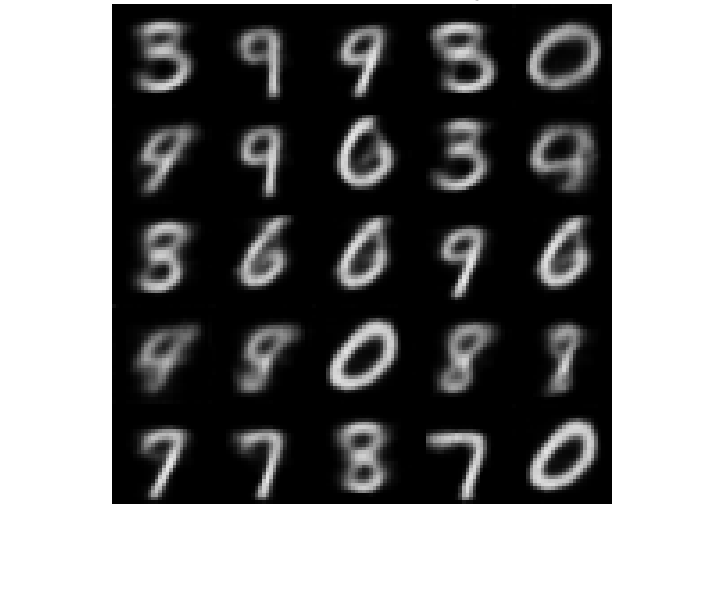

generate(decoderNet_trained_test7, latentspace_Dimension);

Test8

Change the learning rate for the modified n/w

latentspace_Dimension = 2;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 50;
batchSize = 512;
learningrate = 1e-4;
momentum =[];
[encoderNet_trained_test8,decoderNet_trained_test8]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 47.6916. Time taken for epoch = 42.5195s
Epoch : 2 Test ELBO loss = 32.9515. Time taken for epoch = 41.6732s
Epoch : 3 Test ELBO loss = 30.1914. Time taken for epoch = 41.8878s
Epoch : 4 Test ELBO loss = 29.0628. Time taken for epoch = 43.3537s
Epoch : 5 Test ELBO loss = 28.1495. Time taken for epoch = 44.3803s
Epoch : 6 Test ELBO loss = 27.4398. Time taken for epoch = 42.639s
Epoch : 7 Test ELBO loss = 26.9644. Time taken for epoch = 40.6449s
Epoch : 8 Test ELBO loss = 26.6875. Time taken for epoch = 41.5457s
Epoch : 9 Test ELBO loss = 26.4624. Time taken for epoch = 40.5266s
Epoch : 10 Test ELBO loss = 26.2556. Time taken for epoch = 40.2244s
Epoch : 11 Test ELBO loss = 26.0851. Time taken for epoch = 41.4337s
Epoch : 12 Test ELBO loss = 25.9118. Time taken for epoch = 40.9183s
Epoch : 13 Test ELBO loss = 25.7236. Time taken for epoch = 40.7535s
Epoch : 14 Test ELBO loss = 25.519. Time taken for epoch = 40.4083s
Epoch : 15 Test ELBO loss = 25.4036. Time tak

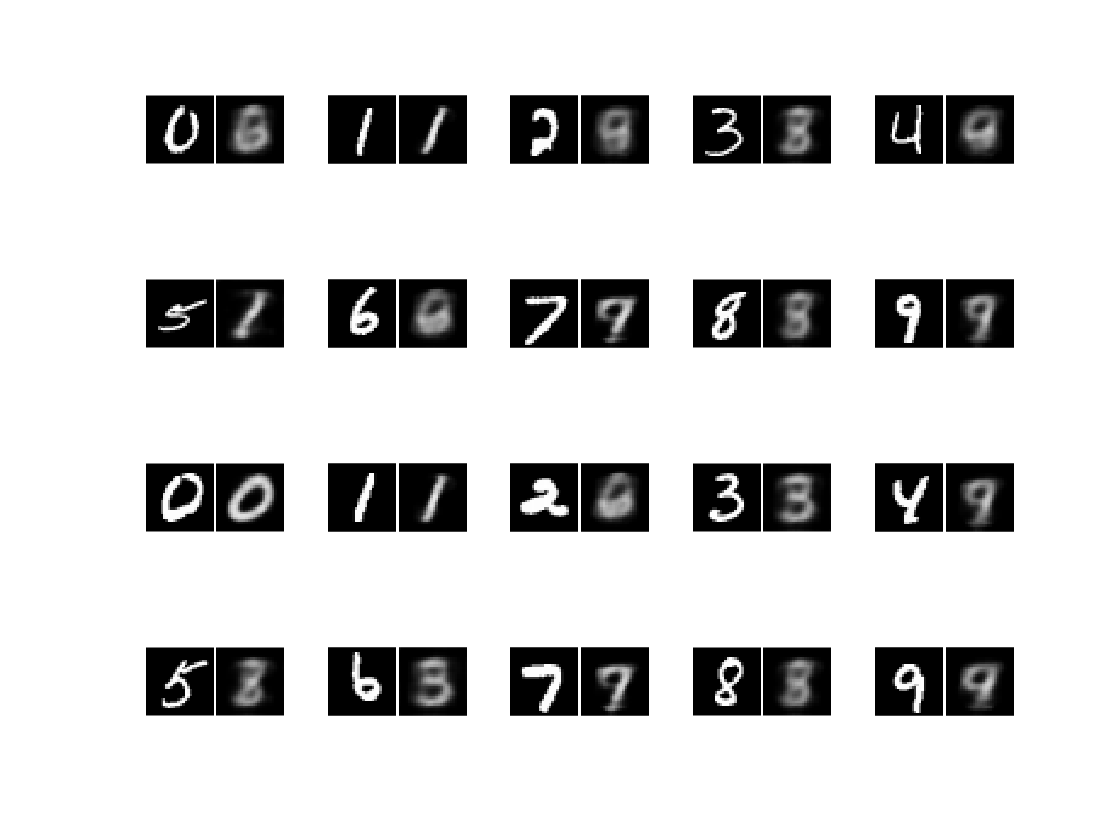

visualizeReconstruction(test_images, test_labels, encoderNet_trained_test8,decoderNet_trained_test8);

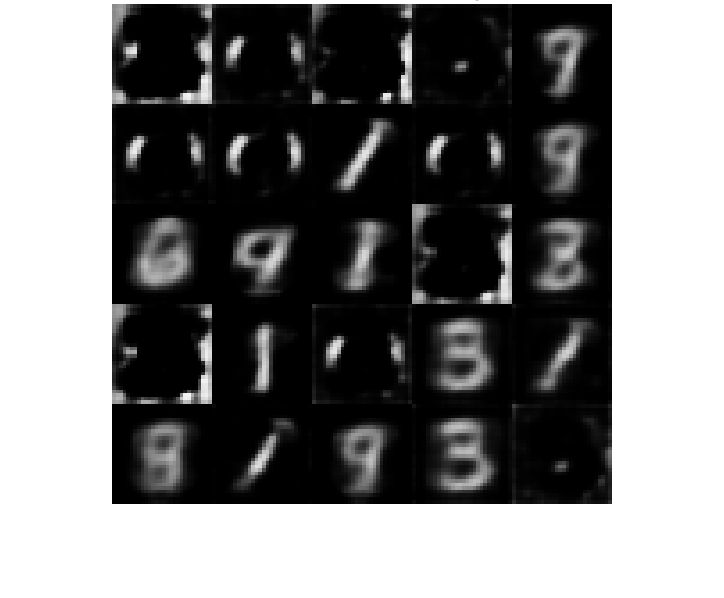

generate(decoderNet_trained_test8, latentspace_Dimension);

Test9

Test5 : Using sgdm optimizer by replacing adam by changing the momentum = 0.6

latentspace_Dimension = 2;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 50;
batchSize = 512;
learningrate = 1e-3;
momentum =0.6;
[encoderNet_trained_test9,decoderNet_trained_test9]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'sgdm');

Epoch : 1 Test ELBO loss = 38.3171. Time taken for epoch = 42.363s
Epoch : 2 Test ELBO loss = 37.9924. Time taken for epoch = 40.784s
Epoch : 3 Test ELBO loss = 37.7161. Time taken for epoch = 40.6638s
Epoch : 4 Test ELBO loss = 37.4635. Time taken for epoch = 40.5596s
Epoch : 5 Test ELBO loss = 37.2514. Time taken for epoch = 40.604s
Epoch : 6 Test ELBO loss = 37.0843. Time taken for epoch = 40.6367s
Epoch : 7 Test ELBO loss = 36.9563. Time taken for epoch = 40.7089s
Epoch : 8 Test ELBO loss = 36.8479. Time taken for epoch = 40.5497s
Epoch : 9 Test ELBO loss = 36.7402. Time taken for epoch = 40.6819s
Epoch : 10 Test ELBO loss = 36.6139. Time taken for epoch = 40.4712s
Epoch : 11 Test ELBO loss = 36.4436. Time taken for epoch = 40.3626s
Epoch : 12 Test ELBO loss = 36.182. Time taken for epoch = 40.2616s
Epoch : 13 Test ELBO loss = 35.7699. Time taken for epoch = 40.4003s
Epoch : 14 Test ELBO loss = 34.9977. Time taken for epoch = 40.4861s
Epoch : 15 Test ELBO loss = 30.2695. Time taken

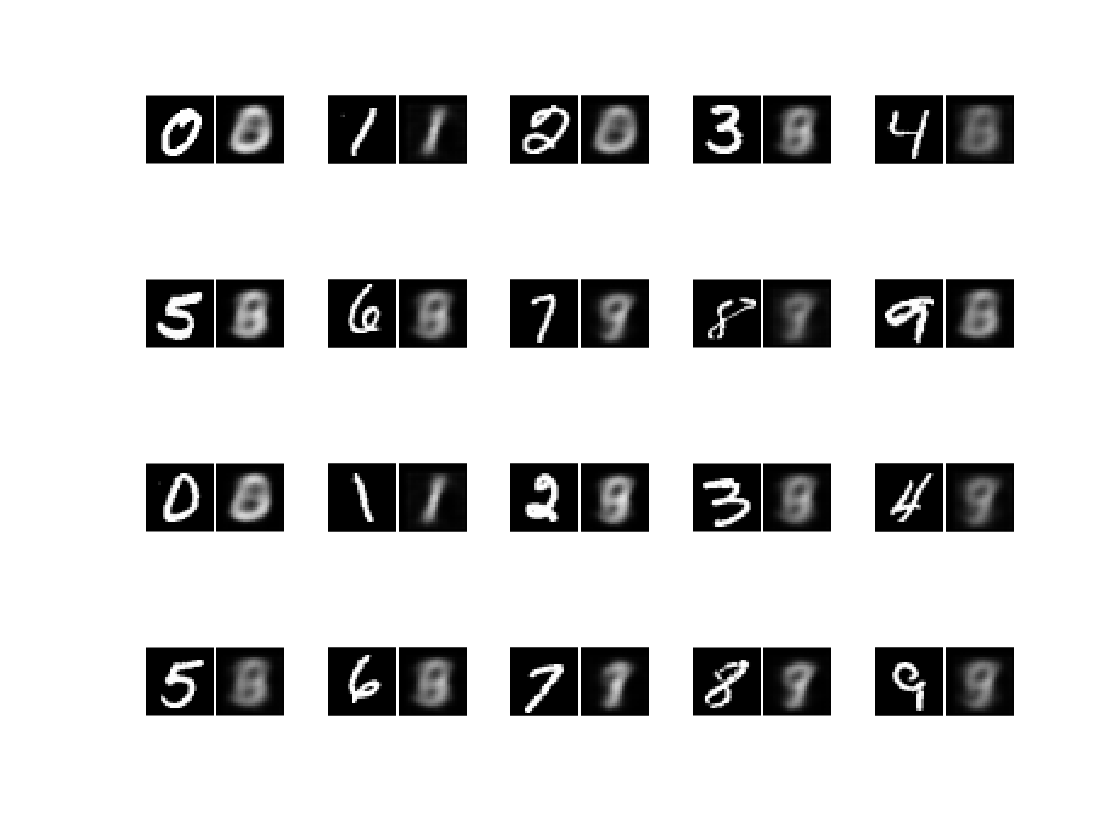

visualizeReconstruction(test_images, test_labels, encoderNet_trained_test9,decoderNet_trained_test9);

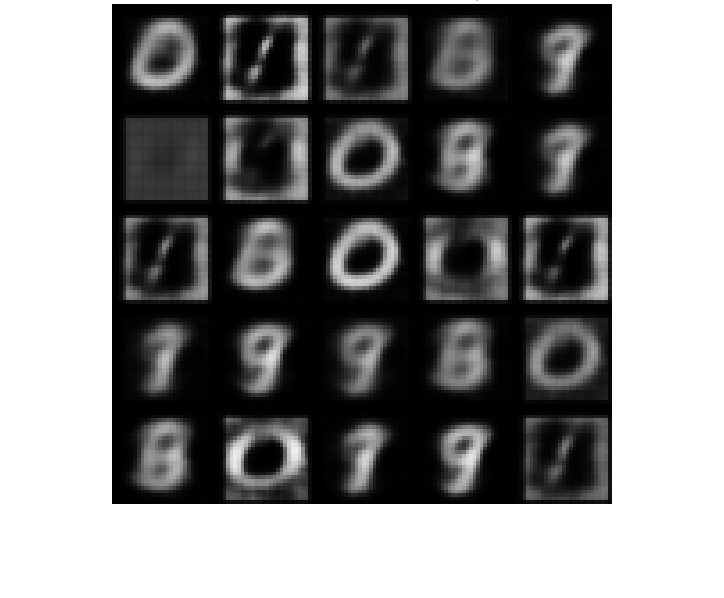

generate(decoderNet_trained_test9, latentspace_Dimension);

Test 10:

Changed the latent space dimension to 5D:

latentspace_Dimension = 5;
image_Size = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);


number_of_Epochs = 50;
batchSize = 512;
learningrate = 1e-3;
momentum =[];
[encoderNet_trained_test10,decoderNet_trained_test10]= train_Network(train_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 27.7144. Time taken for epoch = 43.6864s
Epoch : 2 Test ELBO loss = 25.8176. Time taken for epoch = 40.6793s
Epoch : 3 Test ELBO loss = 23.9384. Time taken for epoch = 42.1897s
Epoch : 4 Test ELBO loss = 23.1543. Time taken for epoch = 41.7275s
Epoch : 5 Test ELBO loss = 21.3291. Time taken for epoch = 41.1803s
Epoch : 6 Test ELBO loss = 20.8509. Time taken for epoch = 41.4745s
Epoch : 7 Test ELBO loss = 20.5509. Time taken for epoch = 42.8981s
Epoch : 8 Test ELBO loss = 20.333. Time taken for epoch = 41.0263s
Epoch : 9 Test ELBO loss = 20.1636. Time taken for epoch = 41.8023s
Epoch : 10 Test ELBO loss = 20.1061. Time taken for epoch = 43.315s
Epoch : 11 Test ELBO loss = 19.9956. Time taken for epoch = 41.039s
Epoch : 12 Test ELBO loss = 19.9454. Time taken for epoch = 40.9751s
Epoch : 13 Test ELBO loss = 19.7823. Time taken for epoch = 43.6199s
Epoch : 14 Test ELBO loss = 19.7531. Time taken for epoch = 41.4193s
Epoch : 15 Test ELBO loss = 19.6577. Time take

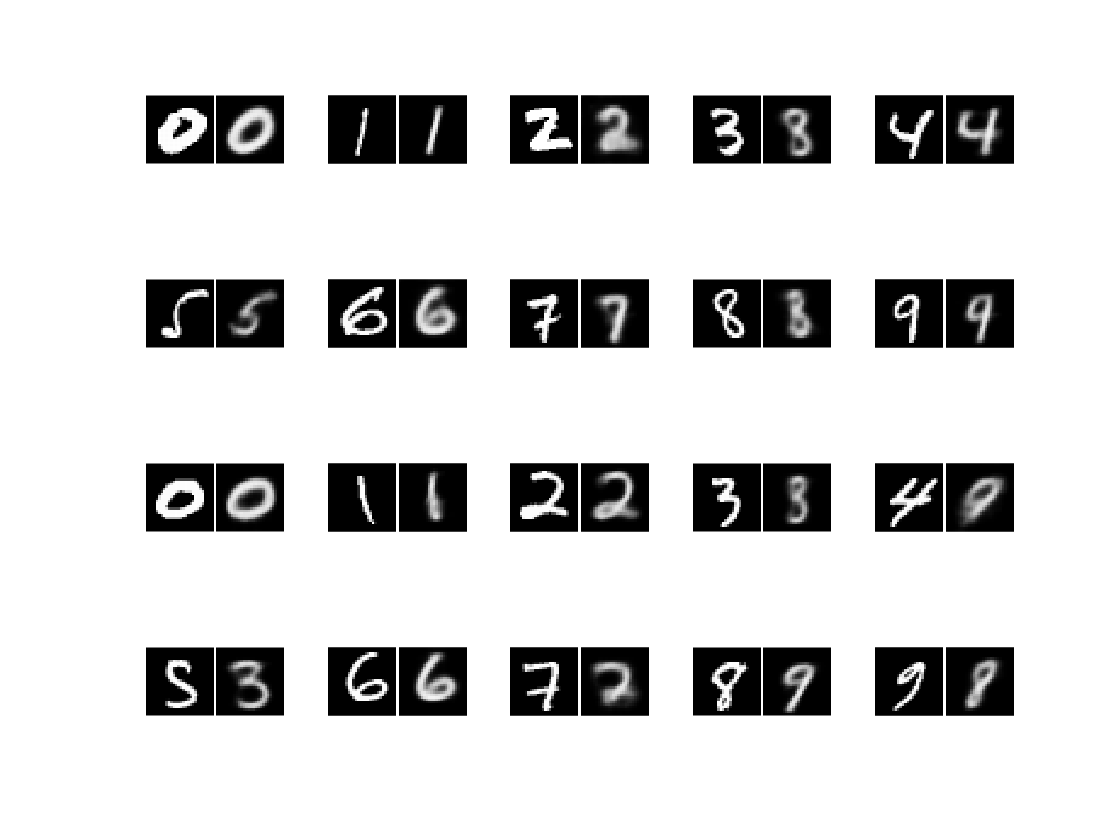

visualizeReconstruction(test_images, test_labels, encoderNet_trained_test10,decoderNet_trained_test10);

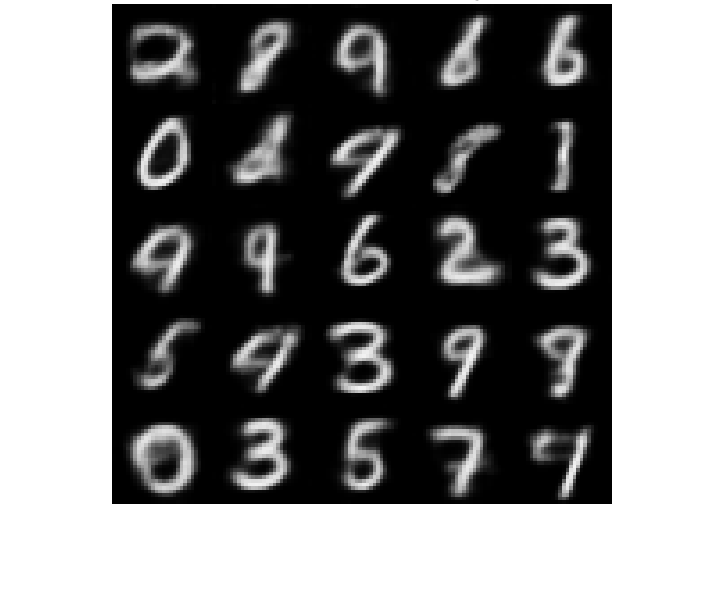

generate(decoderNet_trained_test10, latentspace_Dimension);

## Advanced part:

Classifier network

layers = cnn_classifier();
Xtrain = extractdata(train_images)

Xtrain = Xtrain(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         

net = trainClassifier(layers, Xtrain, train_labels);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        3.91% |       2.3080 |          0.0010 |
|       1 |          50 |       00:00:03 |       84.38% |       0.5142 |          0.0010 |
|       1 |         100 |       00:00:06 |       92.19% |       0.3003 |          0.0010 |
|       1 |         150 |       00:00:08 |       92.19% |       0.2599 |          0.0010 |
|       1 |         200 |       00:00:10 |       94.53% |       0.2319 |          0.0010 |
|       1 |         250 |       00:00:13 |       96.09% |       0.1161 |          0.0010 |
|       1 |         300 |  

Ytest = extractdata(test_images);
predict_labels = classify(net, Ytest);
Accur = sum(predict_labels == test_labels)/numel(test_labels)*100;
disp(['Accuracy achieved : ' num2str(Accur)]);

Accuracy achieved : 98.86



half_dataset_MNIST=size(train_images,4)/2;
first_half_MNIST_dataset_images = extractdata(train_images(:,:,1,1:half_dataset_MNIST));
first_half_MNIST_dataset_labels = train_labels(1:half_dataset_MNIST);
n =[0.2 0.5 1];
num_VAE_image= n*half_dataset_MNIST;

 VAE for half of MNIST data set

number_of_Epochs =20;
momentum =0.6;
latentspace_Dimension =2;
batchSize = 512;
learningrate = 1e-3;

image_Size = [28 28 1];
encoderLG = layerGraph([
    imageInputLayer(image_Size,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(2 * latentspace_Dimension, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentspace_Dimension],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose5')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

[encoderNet_final,decoderNet_final]= train_Network(first_half_MNIST_dataset_images,test_images,encoderNet,decoderNet,number_of_Epochs,batchSize, learningrate, momentum, 'adam');

Epoch : 1 Test ELBO loss = 30.803. Time taken for epoch = 25.4767s
Epoch : 2 Test ELBO loss = 27.5533. Time taken for epoch = 22.2101s
Epoch : 3 Test ELBO loss = 26.5643. Time taken for epoch = 22.1314s
Epoch : 4 Test ELBO loss = 26.1122. Time taken for epoch = 21.8767s
Epoch : 5 Test ELBO loss = 25.7041. Time taken for epoch = 22.1781s
Epoch : 6 Test ELBO loss = 25.2577. Time taken for epoch = 22.0012s
Epoch : 7 Test ELBO loss = 24.7762. Time taken for epoch = 21.8708s
Epoch : 8 Test ELBO loss = 24.3948. Time taken for epoch = 22.1365s
Epoch : 9 Test ELBO loss = 24.1589. Time taken for epoch = 22.2612s
Epoch : 10 Test ELBO loss = 23.9874. Time taken for epoch = 21.9049s
Epoch : 11 Test ELBO loss = 23.8258. Time taken for epoch = 22.044s
Epoch : 12 Test ELBO loss = 23.6625. Time taken for epoch = 22.2194s
Epoch : 13 Test ELBO loss = 23.5138. Time taken for epoch = 21.9421s
Epoch : 14 Test ELBO loss = 23.3395. Time taken for epoch = 21.9085s
Epoch : 15 Test ELBO loss = 23.1805. Time tak

The_other_half_MNIST_images= (train_images(:,:,:,half_dataset_MNIST+1:half_dataset_MNIST+max(num_VAE_image)));
The_other_half_MNIST_labels = train_labels(half_dataset_MNIST+1:half_dataset_MNIST+max(num_VAE_image));

tic
 count=1;
for i=1:size(The_other_half_MNIST_images,4)/10
    for c=0:9
        index = The_other_half_MNIST_labels == categorical(c);
        index=find(index);
        index = index(randi(numel(index),1));
        X = The_other_half_MNIST_images(:,:,:,index);
        [z, ~, ~] = sampling(encoderNet_final, X);
                randomNoise = dlarray(randn(1,1,latentspace_Dimension,1),'SSCB');
        z = z + randomNoise;
        XPred = sigmoid(forward(decoderNet_final, z));
        VAE_images(:,:,:,count) = gather(extractdata(XPred));
        VAE_labels(count) = The_other_half_MNIST_labels(index);
        
        count =count+1;
    end
end
toc

Elapsed time is 150.921683 seconds.


for k=1:numel(n)
    
    MNIST_images = extractdata(train_images(:,:,:,half_dataset_MNIST+1:half_dataset_MNIST+num_VAE_image(k)));
    MNIST_labels = train_labels(half_dataset_MNIST+1:half_dataset_MNIST+num_VAE_image(k));
    test_image =cat(4,MNIST_images(:,:,:,1:num_VAE_image(k)),double(VAE_images(:,:,:,1:num_VAE_image(k))));
    test_label =[MNIST_labels(1:num_VAE_image(k));VAE_labels(1:num_VAE_image(k))'];
    classify_layers = cnn_classifier();
    net=trainClassifier(classify_layers, test_image, test_label);
    Ytest = extractdata(test_images)
    predict = classify(net, Ytest);
Accuracy = sum(predict == test_labels)/numel(test_labels)*100;
line =sprintf('Accuracy : %s percentage for %s percentage of data', num2str(Accuracy),num2str(n(k)*100));
disp(line);
end

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       11.72% |       2.3023 |          0.0010 |
|       1 |          50 |       00:00:02 |       53.91% |       1.5134 |          0.0010 |
|       2 |         100 |       00:00:05 |       52.34% |       1.5167 |          0.0010 |
|       2 |         150 |       00:00:07 |       57.03% |       1.2641 |          0.0010 |
|       3 |         200 |       00:00:10 |       60.94% |       1.1709 |          0.0010 |
|       3 |         250 |       00:00:12 |       57.81% |       1.1979 |          0.0010 |
|       4 |         300 |  

Ytest = Ytest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0 

Accuracy : 96.28 percentage for 20 percentage of data


Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       15.62% |       2.3084 |          0.0010 |
|       1 |          50 |       00:00:02 |       43.75% |       1.5498 |          0.0010 |
|       1 |         100 |       00:00:05 |       54.69% |       1.3298 |          0.0010 |
|       1 |         150 |       00:00:07 |       54.69% |       1.2327 |          0.0010 |
|       1 |         200 |       00:00:10 |       59.38% |       1.1461 |          0.0010 |
|       2 |         250 |       00:00:12 |       62.50% |       1.0076 |          0.0010 |
|       2 |         300 |  

Ytest = Ytest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0 

Accuracy : 97.79 percentage for 50 percentage of data


Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       12.50% |       2.3074 |          0.0010 |
|       1 |          50 |       00:00:02 |       48.44% |       1.5921 |          0.0010 |
|       1 |         100 |       00:00:04 |       57.03% |       1.2786 |          0.0010 |
|       1 |         150 |       00:00:06 |       56.25% |       1.2904 |          0.0010 |
|       1 |         200 |       00:00:08 |       56.25% |       1.2978 |          0.0010 |
|       1 |         250 |       00:00:11 |       57.81% |       1.2147 |          0.0010 |
|       1 |         300 |  

Ytest = Ytest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0 

Accuracy : 98.58 percentage for 100 percentage of data
